%% Initializations
clc; clear; close all;

g = 9.81;   % The gravitational acceleration [m/s^2]
l =  0.2;   % Distance from the center of mass to each rotor [m]
m =  0.5;   % Total mass of the quadrotor [kg]
I = [1.24, 1.24, 2.48]; % Mass moment of inertia [kg m^2]
mu = 2.0;   % Maximum thrust of each rotor [N]
sigma = 0.01; % The proportionality constant relating thrust to torque [m]


p = [g l m I mu sigma];


% Initial conditions
z0 = zeros(12,1);


r = [0; 0; 0];
n = [0; 0; 0];
%u = [1; 1.1; 1.9; 1.2]; % Original "u"
u = [1; 1.5; 1; 1.5]; % u1 across from u3 (CCW), u2 across from u4 (CW)

% Desired Point
xd = [0; 0; .3];

Notes to self:

(0.5 seems to be the minium difference between the two pairs of props to have a positive effect i nthe Z direction.)

So, we need to create a controller which "Hovers" the copter.

In concept, the copter approaches a point and attempts to maintain it. 

So, given an (x,y,z), the chopter zips over and bobs at the point with  positive"x" being the direction of Prop 1, and positive "y" in the direction of Prop 2.

Dissection: Given a position, the copter needs to check it's current position relative to the goal (reference). To get the coper going in the positive X, Prop 3 has to be applying more force than Prop 1, Vise Versa. 

This could be translated in leaning left, right or back, forth OR Pitch and Roll

We will need a fucntion which takes a desired point and repeatedly checks current position versus desired, creates an error for each distance (Xd - [z(1),z(2),z(3)]), and then adjusts power (u) based on this. The (u) will need to be input back into 

so, we have to change (u) into a function 

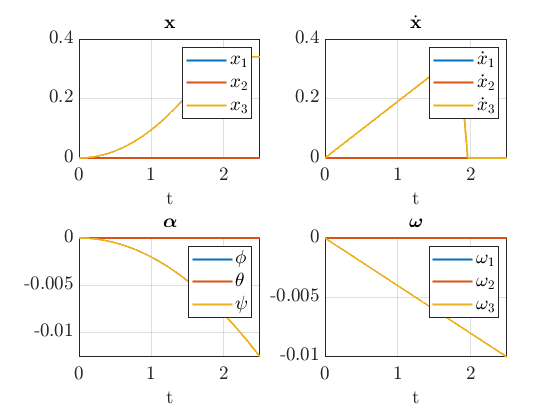


%% Solving the initial-value problem

t = linspace(0, 2.5, 500);

[t,z] = ode45(@(t,z) quadrotor(t, z, u, p, r, n,xd), t, z0);
%[t,z] = ode45(@(t,z) quadrotor(t, z, u, p, r, n, xd), t, z0);

%% Plotting the results

for i=1:4
    ax(i) = subplot(2,2,i,'NextPlot','Add','Box','on','XGrid','on','YGrid','on',...
                'Xlim',[t(1), t(end)],...
                'TickLabelInterpreter','LaTeX','FontSize',14);
    xlabel('t','Interpreter','LaTeX','FontSize',14);        
end


plot(ax(1), t,z(:,1:3), 'LineWidth', 1.5);
legend(ax(1), {'$x_1$', '$x_2$', '$x_3$'},... 
    'Interpreter', 'LaTeX', 'FontSize', 14);
title(ax(1), '${\bf x}$','Interpreter','LaTeX','FontSize',14);
xlabel(ax(1), 't','Interpreter','LaTeX','FontSize',14);

plot(ax(3), t, z(:,4:6), 'LineWidth', 1.5);
legend(ax(3), {'$\phi$', '$\theta$', '$\psi$'},...
    'Interpreter', 'LaTeX', 'FontSize', 14);
title(ax(3), '\boldmath$\alpha$','Interpreter','LaTeX','FontSize',14);

plot(ax(2), t, z(:,7:9), 'LineWidth', 1.5);
legend(ax(2), {'$\dot{x}_1$', '$\dot{x}_2$', '$\dot{x}_3$'},...
    'Interpreter', 'LaTeX', 'FontSize', 14);
title(ax(2), '$\dot{\bf x}$','Interpreter','LaTeX','FontSize',14);

plot(ax(4), t, z(:,10:12), 'LineWidth', 1.5);
legend(ax(4), {'$\omega_1$', '$\omega_2$', '$\omega_3$'},...
    'Interpreter', 'LaTeX', 'FontSize', 14);
title(ax(4), '\boldmath$\omega$','Interpreter','LaTeX','FontSize',14);

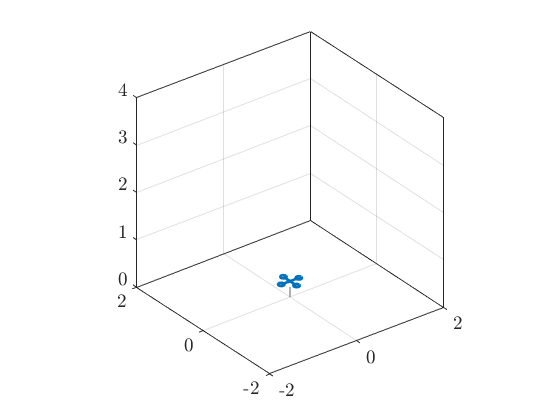




%% Animation
animation_fig = figure;

airspace_box_length = 4;

animation_axes = axes('Parent', animation_fig,...
    'NextPlot','add','DataAspectRatio',[1 1 1],...
    'Xlim',airspace_box_length*[-0.5 0.5],...
    'Ylim',airspace_box_length*[-0.5 0.5],...
    'Zlim',airspace_box_length*[0 1],...
    'box','on','Xgrid','on','Ygrid','on','Zgrid','on',...
    'TickLabelInterpreter','LaTeX','FontSize',14);

view(animation_axes, 3);

N = 10;
Q = linspace(0,2*pi,N)';
circle = 0.3*l*[cos(Q) sin(Q) zeros(N,1)];
loc = l*[1 0 0; 0 1 0; -1 0 0; 0 -1 0];


silhouette = plot3(0,0,0, '--', 'Color', 0.5*[1 1 1], 'LineWidth', 1 ,...
    'Parent', animation_axes);
body = plot3(0,0,0, 'Color',lines(1), 'LineWidth', 2,...
        'Parent', animation_axes);
for i=1:4
    rotor(i) = plot3(0,0,0, 'Color', lines(1), 'LineWidth', 2,...
        'Parent', animation_axes);
end

tic;
for k=1:length(t)
    
    R = [ cos(z(k,5))*cos(z(k,6)), sin(z(k,4))*sin(z(k,5))*cos(z(k,6)) - cos(z(k,4))*sin(z(k,6)), sin(z(k,4))*sin(z(k,6)) + cos(z(k,4))*sin(z(k,5))*cos(z(k,6));
          cos(z(k,5))*sin(z(k,6)), cos(z(k,4))*cos(z(k,6)) + sin(z(k,4))*sin(z(k,5))*sin(z(k,6)), cos(z(k,4))*sin(z(k,5))*sin(z(k,6)) - sin(z(k,4))*cos(z(k,6));
                     -sin(z(k,5)),                                 sin(z(k,4))*cos(z(k,5)),                                 cos(z(k,4))*cos(z(k,5))];
    for i=1:4
        ctr(i,:) = z(k,1:3) + loc(i,:)*R';
        pose = ones(N,1)*z(k,1:3) + (ones(N,1)*loc(i,:) + circle)*R';
        set(rotor(i), 'XData', pose(:,1), 'YData', pose(:,2),  'ZData', pose(:,3) );
         
    end
    set(silhouette,'XData', [0, z(k,1), z(k,1), z(k,1)],...
        'YData', [0, 0, z(k,2), z(k,2)],...
        'ZData', [0, 0, 0, z(k,3)]);
    set(body, 'XData', [ctr([1 3],1); NaN; ctr([2 4],1)], ...
        'YData', [ctr([1 3],2); NaN; ctr([2 4],2)],...
        'ZData', [ctr([1 3],3); NaN; ctr([2 4],3)] );
    pause(t(k)-toc);
    pause(0.01);
end

function dz = quadrotor(t, z, u, p, r, n, xd) % (GOTTA INCLUDE xd TO MAKE THIS WORK )
% State vector definition
%
%      x1, x2, x3, phi, theta, psi, dx1, dx2, dx3, omega1, omega2, omega3
% z = [z1, z2, z3,  z4,    z5,  z6,  z7,  z8,  z9,    z10,    z11,    z12]
%
% Parameter vector definition
%
%       g,  l,  m, I11, I22, I33, mu, sigma
% p = [p1, p2, p3,  p4,  p5,  p6, p7,    p8]


% Forming the moment of inertia tensor based on the parametr values
I = diag(p(4:6)); 


% Rotation matrix mapping body fixed frame C to inertial frame E
R = [ cos(z(5))*cos(z(6)), sin(z(4))*sin(z(5))*cos(z(6)) - cos(z(4))*sin(z(6)), sin(z(4))*sin(z(6)) + cos(z(4))*sin(z(5))*cos(z(6));
      cos(z(5))*sin(z(6)), cos(z(4))*cos(z(6)) + sin(z(4))*sin(z(5))*sin(z(6)), cos(z(4))*sin(z(5))*sin(z(6)) - sin(z(4))*cos(z(6));
               -sin(z(5)),                                 sin(z(4))*cos(z(5)),                                 cos(z(4))*cos(z(5))];

           

%%%%%%%%%%%%%%%%%%%%%%%%% ADDED CONTENT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% First the Error...
err = -(xd -[z(1); z(2); z(3)])./xd; % Needs to be analog, 0.0 to 1.0

% Current Velocity
v = [z(7); z(8); z(9)];

u = fuzzyControlHeight(err,u,v);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Adjusting thrust output based on feasible limits
u = max( min(u, p(7)), 0);



% Computing temporary variables

% rt = torque vector induced by rotor thrusts
rt = [                   ( u(2) - u(4) )*p(2); 
                         ( u(3) - u(1) )*p(2); 
           ( u(1) - u(2) + u(3) - u(4) )*p(8)];


% Computing time derivative of the state vector
dz(1:3,1) = z(7:9,1);

dz(4:6,1) = [ z(10) + z(12)*cos(z(4))*tan(z(5)) + z(11)*sin(z(4))*tan(z(5));
                                          z(11)*cos(z(4)) - z(12)*sin(z(4));
                              (z(12)*cos(z(4)) + z(11)*sin(z(4)))/cos(z(5))];
                      
dz(7:9,1) = R*([0; 0; sum(u)] + r)/p(3) - [0; 0; p(1)];

dz(10:12,1) = I\( rt + n - cross( z(10:12,1) , I * z(10:12,1) ) );
end

function v = fuzzyControlHeight(errH,u,v)

    zErr = errH(3);
    
    zVel = v(3);
    
    delta = 0;

    if zErr < 0.3 && zErr < 0 && zVel > 1 && zVel > 0 % Error Small / Positive, Velocity Large / Positive 
        
        %v = [1; 1.452525; 1; 1.452525];
        
        delta = (-zErr * 3)*ones(4,1);
        
    elseif zErr < 0.3 && zErr < 0 && zVel > 1 && zVel < 0 % Error Small / Positive, Velocity Large / Negative 
        
        delta = (zErr * 3)*ones(4,1);
        
    elseif zErr < 0.3 && zErr > 0 && zVel > 1 && zVel > 0 % Error Small / Negative, Velocity Large / Positive 
        
        delta = (zErr * 3)*ones(4,1);
        
    elseif zErr < 0.3 && zErr > 0 && zVel > 1 && zVel < 0 % Error Small / Negative, Velocity Large / Negative 
        
        delta = (-zErr * 3)*ones(4,1);
        
    elseif zErr > 0.3 && zErr > 0 && zVel > 1 && zVel > 0 % Error large / Positive, Velocity Large / Positive 
        
        delta = (-zErr * 3 * 2)*ones(4,1);
        
    elseif zErr > 0.3 && zErr < 0 && zVel > 1 && zVel > 0 % Error large / Negative, Velocity Large / Positive 
        
        delta = ((-zErr/2) * 3)*ones(4,1);
        
    elseif zErr > 0.3 && zErr > 0 && zVel > 1 && zVel < 0 % Error large / Negative, Velocity Large / Negative 
        
        delta = (-zErr * 3 * 2)*ones(4,1);
        
    elseif zErr > 0.3 && zErr > 0 && zVel < 1 && zVel > 0 % Error large / Negative, Velocity Small / Positive 
        
        delta = (-zErr * 3)*ones(4,1);
        
    elseif zErr < 0.3 && zErr > 0 && zVel < 1 && zVel > 0 % Error Small / Negative, Velocity Small / Positive 
        
        delta = (-zErr * 3)*ones(4,1);
        
%     else
%         
%         if abs(zErr) > .3
%             
%             zErr = .3*(zErr/abs(zErr));
%             
%         elseif abs(zErr) < .05
%             
%             zErr = .05*(zErr/abs(zErr));
%             
%         end
%         
%         delta = (zErr * 3)*ones(4,1);

    end
    
    v = delta + u;
    
end

function u = fuzzyControlPhi(errPhi)

    

end

function u = fuzzyControlTheta(errTheta)

    

end

function u = fuzzyControlPsi(errTheta)

    

end